n_values = 1:20;
x_values = [1 5];

results = zeros(length(n_values), length(x_values));

for i = n_values
    n = n_values(i);
    for j = 1:length(x_values)
        x = x_values(j);
        f = @(t)(t.^n).*exp(-x*t);
        results(i,j)=integral(f, -1, 1);    
    end
end

res=[n_values',results];
T = array2table(res, 'VariableNames', {'n','x=1', 'x=5'});
disp(T);

format long
n=20;
x=5;
y=IntegralIterad(n,x);
disp(y)

%Question 2 a)
%Testar a função com f(x)=x^2-3
clear
format long
f=@(x)x.^2-3; %definição da função
disp("O zero real da função é: "+fzero(f,4));

O zero real da função é: 1.7321


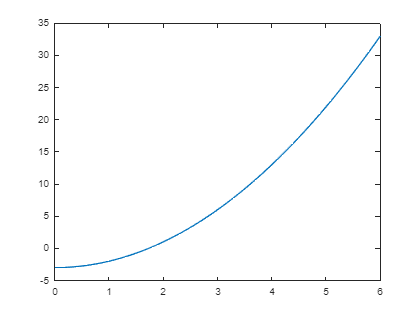

a=0:0.1:6;
plot(a,f(a)) %gráfico da função

[x,erro]=QuasiNewton(f,10^-5,4,10^-7,100); %implementação da função
T=table(x',erro');
T=renamevars(T,["Var1","Var2"],["x","Estimativa de erro |ei-en|"]);
disp(T)

           x            Estimativa de erro |ei-en|
    ________________    __________________________

    2.37500203115003          0.642951223581151   
    1.81908059316994         0.0870297856010604   
    1.73413291242138         0.0020821048525026   
    1.73205206351909       1.25595021471803e-06   
    1.73205080757296       4.08095779391715e-12   
    1.73205080756888                          0   




%Estimativa de coeficiente assimptótico
n=length(x);
p=[0.5 1 2 3 4];
ca1=zeros(n-1,length(p));
for i=1:n-1
    for j=1:length(p)
        ca1(i,j)=erro(i+1)/(erro(i)^p(j));
    end
end
%disp(ca1)
t=table(ca1);
t=renamevars(t,"ca1","Estimativa do coeficiente assimptótico para p=0.5,1,2,3,4");
disp(t)

                                 Estimativa do coeficiente assimptótico para p=0.5,1,2,3,4                              
    ____________________________________________________________________________________________________________________

       0.108537271583337       0.135359856874237       0.210528966910276       0.327441583729568        0.50927904282655
     0.00705778849572394      0.0239240489692442       0.274894954687246        3.15863072382309        36.2936746541244
    2.75246069733516e-05    0.000603211799448251       0.289712498735699        139.144048575401        66828.5501607451
    3.64146291133844e-09    3.24929901368214e-06        2.58712405603723        2059893.79652128        1640107842159.77
                       0                       0                       0                       0                       0



format long
clear
% Question 2b) Produção de energia solar concentrada
h=300;
f=0.85;
d=14;
C=@(t)pi.*(h./cos(t)).^2*f./(0.5*pi*d^2.*(1+sin(t)-0.5*cos(t)));%Função C
F=@(t)C(t)-1250;%Igualar C a 1250 para encontrar o 0
a=linspace(0,pi/7);
b=linspace(0,2*pi)

b =                    0   0.063466518254339   0.126933036508679   0.190399554763018   0.253866073017357   0.317332591271696   0.380799109526036   0.444265627780375   0.507732146034714   0.571198664289053   0.634665182543393   0.698131700797732   0.761598219052071   0.825064737306410   0.888531255560750   0.951997773815089   1.015464292069428   1.078930810323767   1.142397328578107   1.205863846832446   1.269330365086785   1.332796883341124   1.396263401595463   1.459729919849803   1.523196438104142   1.586662956358482   1.650129474612821   1.713595992867160   1.777062511121499   1.840529029375839   1.903995547630178   1.967462065884517   2.030928584138856   2.094395102393195   2.157861620647535   2.221328138901874   2.284794657156213   2.348261175410553   2.411727693664892   2.475194211919231   2.538660730173570   2.602127248427909   2.665593766682249   2.729060284936588   2.792526803190927   2.855993321445267   2.919459839699606   2.982926357953945   3.046392876208284   3.10985939446

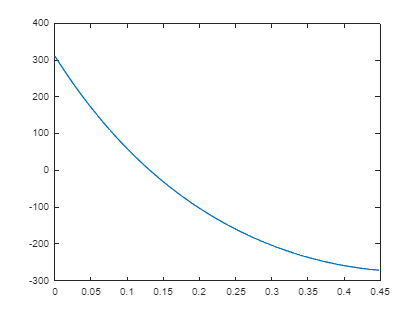

plot(a,F(a));

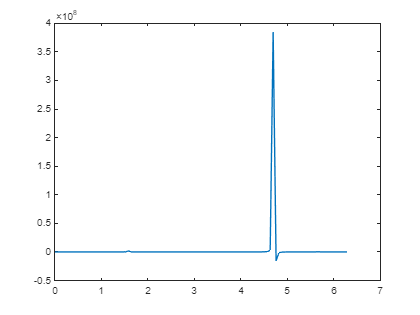

plot(b,F(b));

disp("O zero real da função é: "+fzero(F,pi/10))

O zero real da função é: 0.13147


[t,erro]=QuasiNewton(F,10^-5,pi/10,10^-7,100);
T=table(t',erro');
if (t(length(t))>0&&t(length(t))<pi/10) 
    disp("O valor de theta é estimado é "+t(length(t)))
else disp("Valor de theta não válido")
end

O valor de theta é estimado é 0.13147


T=renamevars(T,["Var1","Var2"],["x","erro"]);
disp(T)

             x                     erro        
    ___________________    ____________________

    0.00787657473296061       0.123596622028886
       0.10312219425939      0.0283510025024565
       0.12977914829686     0.00169404846498641
      0.131466908882305    6.28787954165544e-06
      0.131473196813447     5.1600224093562e-11
      0.131473196761846                       0





for i=1:20
    lam(i)=10^-i;
    [it,err]=QuasiNewton(F,10^-i,pi/10,10^-7,1000); %Implementação da função
    res(i)=it(length(it)); %Valor do theta
    len(i)=length(it); %Número de iteradas
    if len(i)>2 ca(i)=err(end-2)/err(end-3)^2; %Estimativa do coeficiente assimptótico para p=1 
    else ca(i)=-1;
    end
end

T2=table(res',lam',len',ca');
T2=renamevars(T2,["Var1","Var2","Var3","Var4"],["x","delta","iteradas","Coeficiente assimptótico"]);
disp(T2)

            x            delta     iteradas    Coeficiente assimptótico
    _________________    ______    ________    ________________________

    0.131473181427017       0.1       12           209168.303866632    
    0.131473196479693      0.01        7           881.125541312411    
    0.131473196750081     0.001        6          0.875929622421979    
    0.131473196761575    0.0001        6           2.07388412500189    
    0.131473196761846     1e-05        6           2.19105132750379    
    0.131473196761848     1e-06        6           2.20274245870354    
    0.131473196761847     1e-07        6           2.20390989081626    
    0.131473196761848     1e-08        6           2.20401370955797    
    0.131473196761847     1e-09        6           2.20398722705929    
    0.131473196761847     1e-10        6           2.20320820107396    


[it8,err8]=QuasiNewton(F,10^-9,pi/10,10^-7,1000);
for k=1:length(err8)-1
    ca8(k)=err8(k+1)/err8(k)^2;
end
disp(err8')

   0.123586853471878
   0.028348974061518
   0.001694390121699
   0.000006327554507
   0.000000000089424
                   0



disp(ca8')

   1.856063353952159
   2.108330627266339
   2.203987227059291
   2.233479026001171
                   0

